https://blogs.mathworks.com/graphics/2014/10/13/bezier-curves/

## Linear Bezier Curve

initialize points

pt1 = [5;-10];
pt2 = [45;15];

plot

placelabel(pt1, 'pt_1');
placelabel(pt2, 'pt_2');
xlim([0 50])
axis equal %make scaling uniform in x&y

create points in between

t = linspace(0,1,101);
pts = kron((1-t),pt1) + kron(t,pt2)

pts =     5.0000    5.4000    5.8000    6.2000    6.6000    7.0000    7.4000    7.8000    8.2000    8.6000    9.0000    9.4000    9.8000   10.2000   10.6000   11.0000   11.4000   11.8000   12.2000   12.6000   13.0000   13.4000   13.8000   14.2000   14.6000   15.0000   15.4000   15.8000   16.2000   16.6000   17.0000   17.4000   17.8000   18.2000   18.6000   19.0000   19.4000   19.8000   20.2000   20.6000   21.0000   21.4000   21.8000   22.2000   22.6000   23.0000   23.4000   23.8000   24.2000   24.6000
  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500   -5.5000   -5.2500   -5.0000   -4.7500   -4.5000   -4.2500   -4.0000   -3.7500   -3.5000   -3.2500   -3.0000   -2.7500   -2.5000   -2.2500   -2.0000   -1.7500   -1.5000   -1.2500   -1.0000   -0.7500   -0.5000   -0.2500         0    0.2500    0.5000    0.7500    1.0000    1.2500    1.5000    1.7500    2.0000   

plot

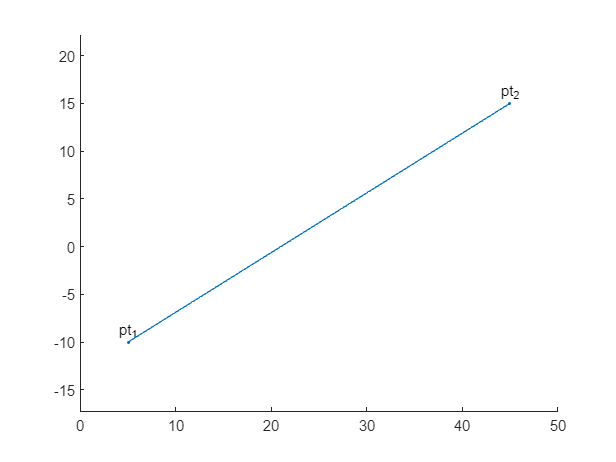

hold on %keep previous plot when adding new plots
plot(pts(1,:),pts(2,:))
hold off

## Quadratic Bezier Curve

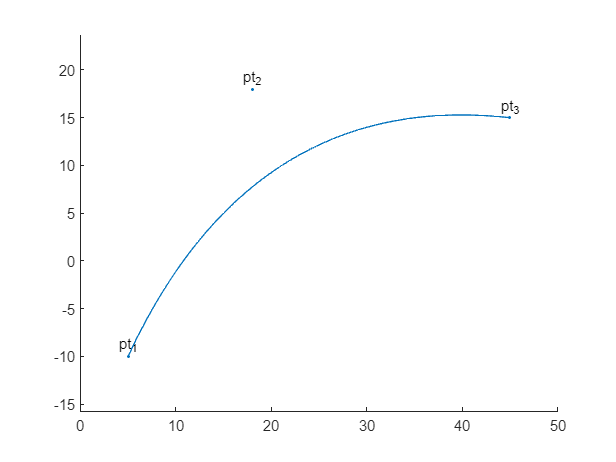

pt1 = [ 5;-10];
pt2 = [18; 18];
pt3 = [45; 15];

cla %clears
placelabel(pt1,'pt_1');
placelabel(pt2,'pt_2');
placelabel(pt3,'pt_3');
xlim([0 50])
axis equal
pts = kron((1-t).^2,pt1) + kron(2*(1-t).*t,pt2) + kron(t.^2,pt3);

hold on
plot(pts(1,:),pts(2,:))
hold off

## Cubic Bezier Curve

pt1 = [ 5;-10];
pt2 = [18; 18];
pt3 = [38; -5];
pt4 = [45; 15];

cla
placelabel(pt1,'pt_1');
placelabel(pt2,'pt_2');
placelabel(pt3,'pt_3');
placelabel(pt4,'pt_4');
xlim([0 50])
axis equal

pts = kron((1-t).^3,pt1) + kron(3*(1-t).^2.*t,pt2) + kron(3*(1-t).*t.^2,pt3) + kron(t.^3,pt4);

hold on
plot(pts(1,:),pts(2,:))
hold off

### Derivative

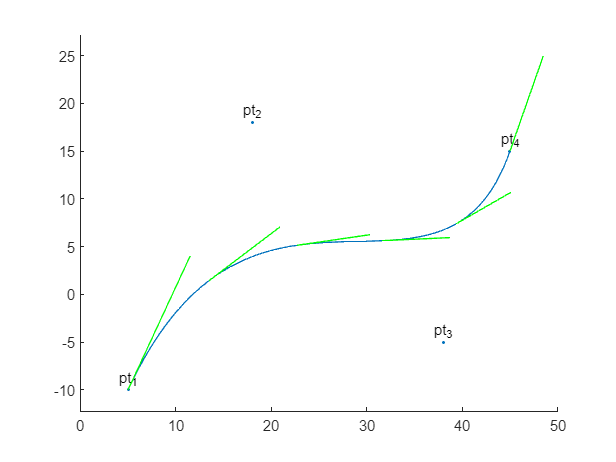

hold on
a = -3*t.^2 +  6*t - 3;
b =  9*t.^2 - 12*t + 3;
c = -9*t.^2 +  6*t;
d =  3*t.^2;

tvec = kron(a,pt1) + kron(b,pt2) + kron(c,pt3) + kron(d,pt4);
for i=1:20:101 %mid number determines spacing (higher = less lines)
    l = line([pts(1,i), pts(1,i)+tvec(1,i)/6], ...
             [pts(2,i), pts(2,i)+tvec(2,i)/6]);
    l.Color = 'green';
end
hold off

## Connecting Bezier Curves

If you want tangency between Bezier curves (trust me you do), the last two points of the first curve hv to be collinear to the first 2 points of the second curve.

cla
xlim([0 50])
axis equal

pt1 = [ 5;-10];
pt2 = [13; -2];
pt3 = [ 5; 20];
pt4 = [25; 20];

placelabel(pt1,'pt_1');
placelabel(pt2,'pt_2');
placelabel(pt3,'pt_3');
placelabel(pt4,'pt_4');

pt5 = [45; 20];
pt6 = [35; -2];
pt7 = [43;-10];

placelabel(pt5,'pt_5');
placelabel(pt6,'pt_6');
placelabel(pt7,'pt_7');

Ensure 3,4,5 collinear

pt4 - pt3

ans =     20
     0


pt5 - pt4

ans =     20
     0


plot

pts1 = kron((1-t).^3,pt1) + kron(3*(1-t).^2.*t,pt2) + kron(3*(1-t).*t.^2,pt3) + kron(t.^3,pt4);
pts2 = kron((1-t).^3,pt4) + kron(3*(1-t).^2.*t,pt5) + kron(3*(1-t).*t.^2,pt6) + kron(t.^3,pt7);

hold on
plot(pts1(1,:),pts1(2,:))
plot(pts2(1,:),pts2(2,:))
hold off

## Curvature Calculations

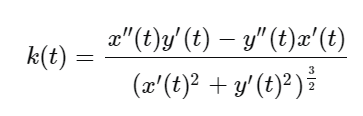(assuming curve goes CCW, otherwise negate)

https://math.stackexchange.com/questions/3276910/cubic-b%C3%A9zier-radius-of-curvature-calculation#:~:text=1%20Answer&text=The%20radius%20of%20curvature%20is,formula's%20no%20good%20to%20you

hold on
a = -3*t.^2 +  6*t - 3;
b =  9*t.^2 - 12*t + 3;
c = -9*t.^2 +  6*t;
d =  3*t.^2;

e = -6*t + 6;
f = 18*t - 12;
g = -18*t + 6;
h = 3*t;

tvec = kron(a,pt1) + kron(b,pt2) + kron(c,pt3) + kron(d,pt4);
avec = kron(e,pt1) + kron(f,pt2) + kron(g,pt3) + kron(h,pt4);

for i=1:40:101 %mid number determines spacing (higher = less lines)
    l = line([pts1(1,i), pts1(1,i)+tvec(1,i)/6], ...
             [pts1(2,i), pts1(2,i)+tvec(2,i)/6]);
    l.Color = 'green';
    cur = (avec(1,i).*tvec(2,i) - avec(2,i).*tvec(1,i))/(tvec(1,i).^2+tvec(2,i).^2).^1.5;
    r = 1/cur;
    r = abs(r)
    %works bc derivative is positive (first curve)
    da = atan2(tvec(2,i),tvec(1,i));
    up = [pts1(1,i)+r*cos(da+pi/2),pts1(2,i)+r*sin(da+pi/2)];
    down = [pts1(1,i)+r*cos(da-pi/2),pts1(2,i)+r*sin(da-pi/2)];
    if avec(2,i)/avec(1,i) > 0
        rp = up
    else
        rp = down
    end
    viscircles(rp,r,'LineWidth',0.5,'LineStyle',":")
    disp(r)
end

r = 9.0510

rp =    11.4000  -16.4000


ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


    9.0510



r = 105.8693

rp =   -94.6928   21.4208


ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


  105.8693



r = 10.3701

rp =    21.9375    9.1404


ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


   10.3701



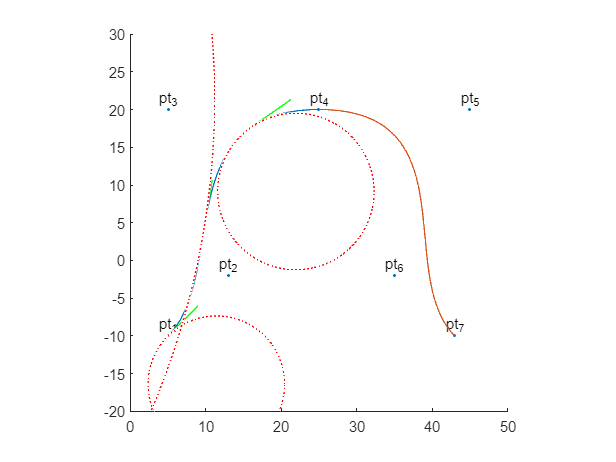

ylim([-20,30])
hold off